## Controls Systems Textbook Example 10.4

### Reset matlab environment

clearvars
close all
clc
s = tf('s');

### Specs: $\zeta=0.04,\ K_v\ge20$


$$G(s)=\frac{40}{s(s+2)}$$


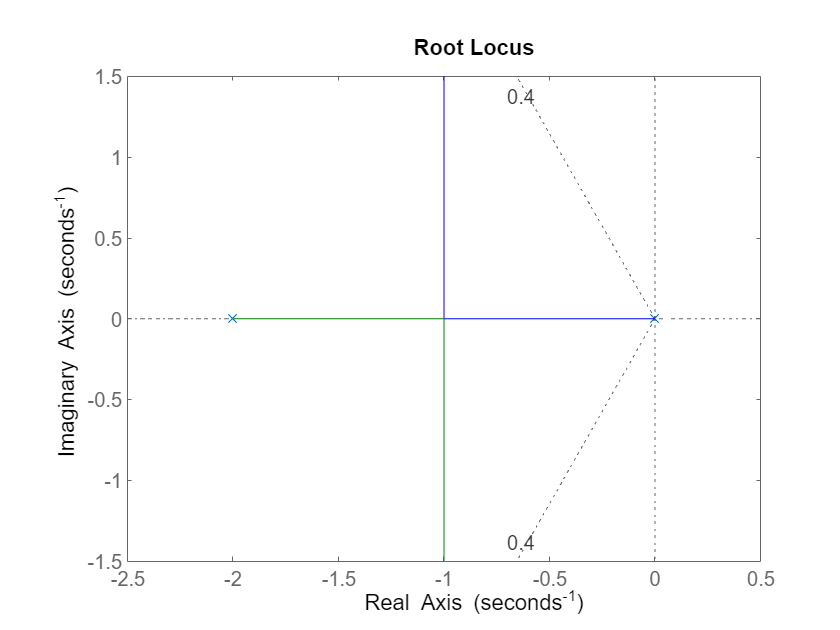

G = 40 / (s*(s+2));   % type 1
rlocus(G), sgrid(.4, 10^4)

### Lead compensator for a type-one system


$$K_v=\frac{40K}{2}\ge20\Rightarrow K\ge1\\
\text{Since no other constraints, let's arbitrarily add the lead compensator.}\\
G_C(s)=\frac{s+5}{s+20}$$


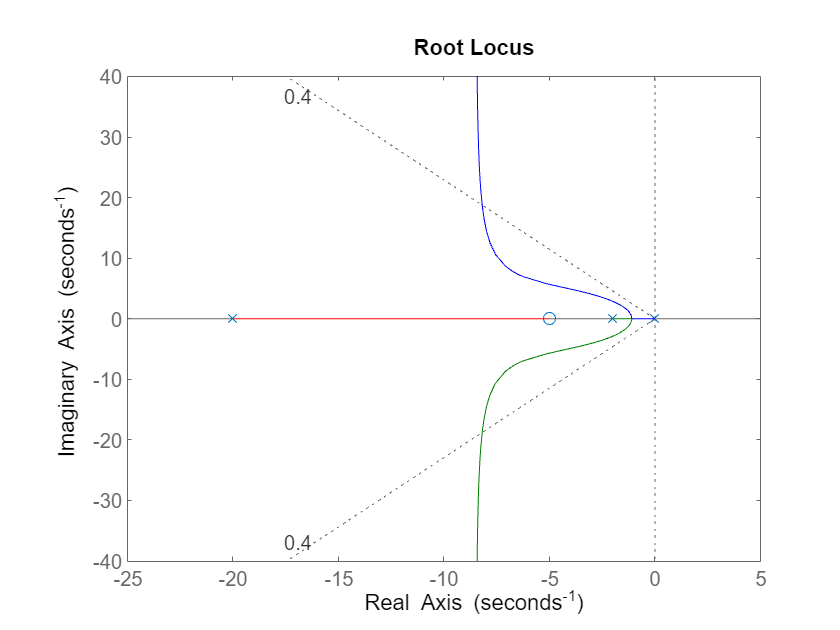

G_C = (s + 5) / (s + 20);
rlocus(G * G_C), sgrid(.4, 10^4)


$$\text{We see from the locus plot that $K=11.8$ when $\zeta=0.4$.}$$


K = 11.8;
L = K * G_C * G;
T = feedback(L, 1);
damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.62e+00                 1.00e+00       5.62e+00         1.78e-01    
 -8.19e+00 + 1.88e+01i     4.00e-01       2.05e+01         1.22e-01    
 -8.19e+00 - 1.88e+01i     4.00e-01       2.05e+01         1.22e-01    


K_v = evalfr(s * L, 10^-10)

K_v = 59.0000

### Bonus: Using a lag compensator for a type-one system


$$K_v=\frac{40K}{2}\ge20\Rightarrow K\ge1\\
\text{But for the original root locus, $K\approx0.156$ when $\zeta=0.4$.}\\
\Rightarrow\ \alpha=\frac{10}{0.156}\approx64\Rightarrow\text{choose }z=0.01$$


K = 9.93;
pzratio = 64;
z = 0.01;
p = z / pzratio;
G_C = (p / z) * (s + z) / (s + p);
L = K * G_C * G;
T = feedback(L, 1);
damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e-02                 1.00e+00       1.00e-02         9.97e+01    
 -9.95e-01 + 2.28e+00i     4.00e-01       2.49e+00         1.00e+00    
 -9.95e-01 - 2.28e+00i     4.00e-01       2.49e+00         1.00e+00    


K_v = evalfr(s * L, 10^-10)

K_v = 198.5999